# Analyzing Re-Alignment

## Recollect all data

load('results_BrainBonus2.mat')
recollect_data

## using woody

test on single subject

t_min = 0;
t_max = 600;
subj_ind = 8;

result = results{subj_ind};
trials = result.trials;
trials = bsxfun(@minus, trials, mean(trials,1));

mask = times > t_min & times < t_max;

[~, woody_shift] = woody(squeeze(trials).*mask', [],[],'thornton','biased');
shift = woody_shift;


aligned_trials = align_trials_by_shift(trials, -shift);
aligned_erp = mean(aligned_trials,2);
sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
% sub_aligned_power = get_norm_spectrum_power(sub_trials_aligned, freqs, SamplingInterval./1000, bl_range);

sub_aligned_power = getPowerSpectra(sub_trials_aligned', SamplingInterval./1000, freqs);
sub_aligned_power = norm_power_bl_range(sub_aligned_power, bl_range);

aligned_power = getPowerSpectra(aligned_trials', SamplingInterval./1000, freqs);
aligned_power = norm_power_bl_range(squeeze(aligned_power), bl_range);

resampled_power = getPowerSpectra(squeeze(trials)', SamplingInterval./1000, freqs);
resampled_power = norm_power_bl_range(squeeze(resampled_power), bl_range);

sub_resampled_trials = bsxfun(@minus, squeeze(trials), squeeze(mean(trials,3)));
sub_power = getPowerSpectra(sub_resampled_trials', SamplingInterval./1000, freqs);
sub_power = norm_power_bl_range(sub_power, bl_range);



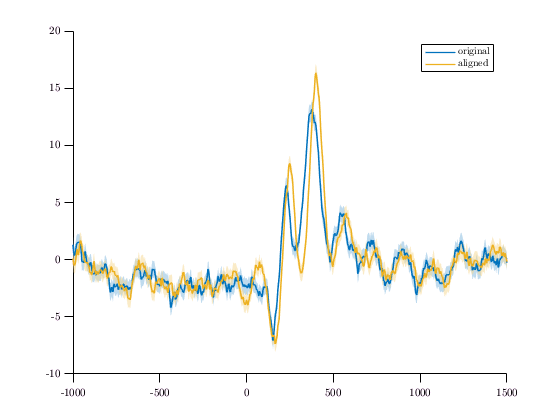

figure;
hold on 
varplot(times, squeeze(trials(:,1,:)))
varplot(times, aligned_trials)
legend({'original', 'aligned'})
 
figure;
title_freq = sprintf('subject=%d, align woody', subj_ind);
show_powers_tight(t, freqs, cat(3, ...
                                squeeze(mean(resampled_power(:,u,:),3)), ...
                                squeeze(mean(sub_power(:,u,:),3)), ...
                                squeeze(mean(resampled_power(:,u,:),3))-median(sub_power(:,u,:),3), ...

                                aligned_power(:,u), ...
                                sub_aligned_power(:,u), ...
                                aligned_power(:,u)-sub_aligned_power(:,u)),...
3, title_freq, 'Power [db]', [], ...
{'original power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'}, ...
[], [], [], 0.1)
colors = cbrewer('div', 'RdBu', 64);
colors = flipud(colors); % puts red on top, blue at the bottom
colormap(colors);

## Total

Align trials

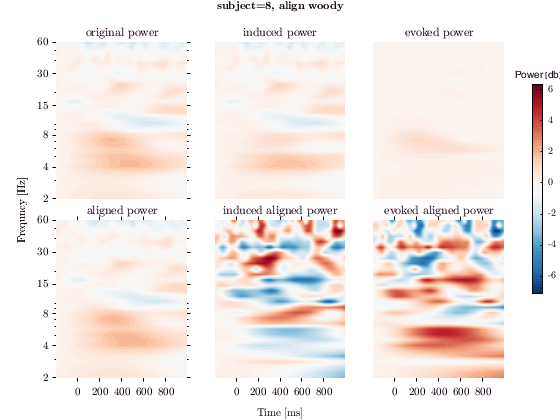

t_min = 0;
t_max = 600;

mask = times > t_min & times < t_max;

total_powers_aligned = zeros([length(freqs), length(times), N_subjects]);
sub_powers_aligned = total_powers_aligned;

total_erps_aligned = zeros([ length(times)  N_subjects]);
total_resampled_power = sub_powers_aligned;
total_sub_resampled = total_resampled_power;

parfor sub_ind = 1:length(results)

    result = results(sub_ind);
    trials = result{1}.trials;
    trials = bsxfun(@minus, trials, mean(trials,1));
    
    mask = times > t_min & times < t_max;
    [~, woody_shift] = woody(squeeze(trials).*mask', [],[],'thornton','biased');
    shift = woody_shift;
    
    aligned_trials = align_trials_by_shift(trials, -shift);
    aligned_erp = mean(aligned_trials,2);
    sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
    % sub_aligned_power = get_norm_spectrum_power(sub_trials_aligned, freqs, SamplingInterval./1000, bl_range);
    
    sub_aligned_power = getPowerSpectra(sub_trials_aligned', SamplingInterval./1000, freqs);
    sub_aligned_power = norm_power_bl_range(sub_aligned_power, bl_range);
    
    aligned_power = getPowerSpectra(aligned_trials', SamplingInterval./1000, freqs);
    aligned_power = norm_power_bl_range(squeeze(aligned_power), bl_range);
    
    resampled_power = getPowerSpectra(squeeze(trials)', SamplingInterval./1000, freqs);
    resampled_power = norm_power_bl_range(squeeze(resampled_power), bl_range);
    
    sub_resampled_trials = bsxfun(@minus, squeeze(trials), squeeze(mean(trials,3)));
    sub_power = getPowerSpectra(sub_resampled_trials', SamplingInterval./1000, freqs);
    sub_power = norm_power_bl_range(sub_power, bl_range);

       
    total_powers_aligned(:,:,sub_ind) = squeeze(aligned_power);        
    sub_powers_aligned  (:,:,sub_ind) = squeeze(sub_aligned_power);
    total_erps_aligned(:,sub_ind) = aligned_erp;
    total_resampled_power(:,:,sub_ind) = squeeze(resampled_power);
    total_sub_resampled(:,:,sub_ind) = squeeze(sub_power);        
end


figure;
title_freq = sprintf('woody averaging');
show_powers_tight(t, freqs, cat(3, ...
                                squeeze(mean(total_resampled_power(:,u,:),3)), ...
                                squeeze(mean(total_sub_resampled(:,u,:),3)), ...
                                squeeze(mean(total_resampled_power(:,u,:),3))-mean(total_sub_resampled(:,u,:),3), ...
                                total_powers_aligned(:,u), ...
                                sub_powers_aligned(:,u), ...
                                total_powers_aligned(:,u)-sub_powers_aligned(:,u)),...
3, title_freq, 'Power [db]', [], ...
{'total power', 'induced power', 'evoked power', 'aligned power', 'induced aligned power', 'evoked aligned power'}, ...
[], [], [], 0.1)
% colormap jet


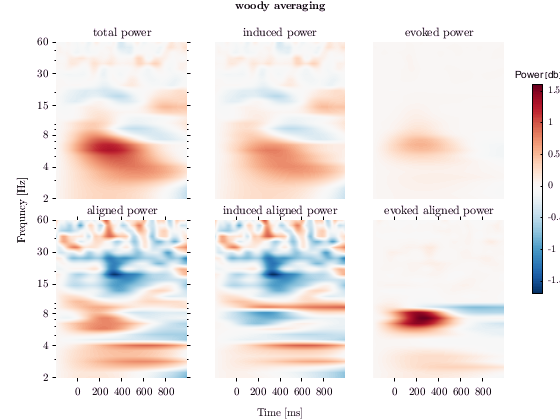

figure;
title_freq = sprintf('resampled (%d X %d)', m, n);

show_powers_tight(t, freqs, cat(3, ...
                                squeeze(mean(total_powers(:,u,:),3)), ...
                                squeeze(mean(sub_powers(:,u,:),3)), ...
                                squeeze(mean(total_powers(:,u,:),3))-mean(sub_powers(:,u,:),3), ...
                                squeeze(mean(total_resampled_power(:,u,:),3)), ...
                                squeeze(mean(total_sub_resampled(:,u,:),3)), ...
                                squeeze(mean(total_resampled_power(:,u,:),3))-mean(total_sub_resampled(:,u,:),3), ...

                                total_powers_aligned(:,u), ...
                                sub_powers_aligned(:,u), ...
                                total_powers_aligned(:,u)-sub_powers_aligned(:,u)),...
3, title_freq, 'Power [db]', [], ...
{'original power', 'induced', 'evoked power', 'resampled power', 'resampled induced', 'resampled evoked', 'aligned power', 'induced aligned power', 'evoked aligned power'}, ...
[], [], [], 0.1)
colormap jet




## Align by cross-correlation (Woody transform)

maxLag = round(100*srate);
shift_func = @(trials) ... 
    cellfun(@(X)-maxLag+output(@()max(xcorr(mean(X,2),X,maxLag)),2), ...
    mat2cell(squeeze(trials)',ones(1,size(trials,3))))';
freq_power_woody = test_time_freq(results, total_powers, sub_powers, total_erps, times, freqs, u, SamplingInterval, bl_range, 100, 0, 0, true, true, shift_func);

## using wavelets

t_zero = 300;
freq_ind = 8:13;
subj_ind = 4;
if isvector(freq_ind)
title_freq = sprintf('@ t = %d ms, f = %.1f-%.1f Hz', t_zero, min(freqs(freq_ind)), max(freqs(freq_ind)));
else
title_freq = sprintf('@ t = %d ms, f = %.1f Hz', t_zero, freqs(freq_ind));
end
result = results{subj_ind };
trials = result.trials;
power = result.original_power;
phases = result.phases;
sub_power = result.sub_power;
% erp = mean(trials(:,1,:),3);
% sub_trials = bsxfun(@minus, trials, erp);
% sub_power = get_norm_spectrum_power(sub_trials, freqs, SamplingInterval./1000, bl_range);
[aligned_trials,woody_shift] = align_by_phase(trials, phases, SamplingInterval, freqs, find(times>t_zero,1), freq_ind);
% aligned_trials = align_trials_by_shift(trials, shift);
aligned_erp = mean(aligned_trials(:,1,:),3);
sub_trials_aligned = bsxfun(@minus, aligned_trials, aligned_erp);
sub_aligned_power = get_norm_spectrum_power(sub_trials_aligned, freqs, SamplingInterval./1000, bl_range);
aligned_power = align_power_by_shift(power, woody_shift);
ERPfigure;
subplot(1,2,1);
varplot(times, squeeze(trials(:,1,:)))
title({num2str(subj_ind), '(subj) original trials'})
subplot(1,2,2);
varplot(times, squeeze(aligned_trials(:,1,:)))
title({'aligned trials, ' title_freq})
ERPfigure;
subplot(2,3,1);
helperCWTTimeFreqPlot(squeeze(mean(power(:,:,u,:),4)), t, freqs, 'surf', {num2str(subj_ind), '(subj) original power', title_freq})
subplot(2,3,2);
helperCWTTimeFreqPlot(squeeze(mean(sub_power(:,:,u,:),4)), t, freqs, 'surf', {'sub power', title_freq})
subplot(2,3,3);
helperCWTTimeFreqPlot(squeeze(mean(power(:,:,u,:),4))-squeeze(mean(sub_power(:,:,u,:),4)), t, freqs, 'surf', {'evoked power', title_freq})
subplot(2,3,4);
helperCWTTimeFreqPlot(squeeze(mean(aligned_power(:,:,u,:),4)), t, freqs, 'surf', {'aligned power' , title_freq})
subplot(2,3,5);
helperCWTTimeFreqPlot(squeeze(mean(sub_aligned_power(:,:,u,:),4)), t, freqs, 'surf', {'sub aligned power', title_freq})
subplot(2,3,6);
helperCWTTimeFreqPlot(squeeze(mean(aligned_power(:,:,u,:),4))-squeeze(mean(sub_aligned_power(:,:,u,:),4)), t, freqs, 'surf', {'evoked aligned power', title_freq})

